# Weather

% Create by Giacomo Mastroddi: August 2023

Open correct ERA5 folder

clear;
close all;

% Change directory to this file
activeDoc = matlab.desktop.editor.getActive;
docPath = activeDoc.Filename;
[dir_path, ~, ~] = fileparts(docPath);
cd(dir_path);

% Open select window
folder_path = "";
while ~contains(folder_path, "ERA5")
    % Get the selected folder path
    folder_path = uigetdir([], 'Choose the ERA5 folder');
    
    % Check if a folder was selected
    if isequal(folder_path, 0)
        disp('No folder selected.');
    else
        disp(['Selected Folder: ' folder_path]);
    end % if
end % while

Selected Folder: C:\Users\giaco\Git_Repositories\aCentauri\ss_offline_data\weather\ERA5


Load and save data to a struct

data_struct = struct();
data_struct.time = {};

% Get a list of all CSV files in the folder with the name "ERA5"
csv_files = dir(fullfile(folder_path, '*ERA5*.csv'));

% Loop through each CSV file and read its data
for i = 1:length(csv_files)
    % Extract time information from the file name
    [~, fname, ~] = fileparts(csv_files(i).name);
    time_parts = strsplit(fname, '_');
    time_info = strrep(time_parts{end}, '-', ':');

    data_struct.time{i} = time_info;
    
    % Read the data from the CSV file
    data = readtable(fullfile(folder_path, csv_files(i).name));
       
    % Add the data columns to the structure
    col_names = data.Properties.VariableNames;
    for j = 1:length(col_names)
        col_name = col_names{j};

        % Convert radiation from J/m^2 to W/m^2 and change name
        if contains(col_name, "Rad")
            new_col_name = strrep(col_name, "Rad_down", "Irr");
            data.(col_name) = data.(col_name) / 3600;
        else
            new_col_name = col_name;
        end % if

        % Create matrices
        if ~isfield(data_struct, new_col_name)
            data_struct.(new_col_name) = [];
        end % if
        data_struct.(new_col_name) = [data_struct.(new_col_name), data.(col_name)];
    end
end % for

Perform wind calculation

% Driving direction decomposition
arclen = [];
data_struct.Azimuth = [];
for k = 1:length(data_struct.lat(:,1))-1
    [arclen(k,1), data_struct.Azimuth(k,1)] = distance(data_struct.lat(k,1), data_struct.lon(k,1), data_struct.lat(k+1,1), data_struct.lon(k+1,1));
end % for
data_struct.Distance = deg2rad(arclen) * earthRadius; % Conversion to meter from degree
data_struct.Cum_distance = cumsum([0; data_struct.Distance]);
drivDirVert = cos(deg2rad(data_struct.Azimuth));
drivDirHori = sin(deg2rad(data_struct.Azimuth));

% Wind decomposition in vertical and horizontal
windVert = cos(deg2rad(data_struct.Wind_dir));
windHori = sin(deg2rad(data_struct.Wind_dir));

% Wind calculation for side and front
data_struct.theta = [];
data_struct.Wind_attack_right = [];
for i = 1:length(csv_files)
    data_struct.theta(:,i) = acos(drivDirVert .* windVert(1:end-1,i) + drivDirHori .* windHori(1:end-1,i)); %minimum angle from drivingDir to Wind_dir
    data_struct.Wind_attack_right(:,i) = data_struct.Azimuth < data_struct.Wind_dir(1:end-1,i);
end % for
data_struct.Wind_attack_left = ~data_struct.Wind_attack_right;
data_struct.beta = data_struct.theta .* data_struct.Wind_attack_left - data_struct.theta .* data_struct.Wind_attack_right;

data_struct.Wind_side = sin(data_struct.theta) .* data_struct.Wind_mean(1:end-1,:); %always positive
data_struct.Wind_front = cos(data_struct.theta) .* data_struct.Wind_mean(1:end-1,:); %positive against driving, negative towards driving

## Plot

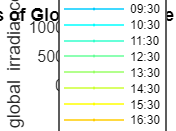

len_time = length(data_struct.time);
colormap_irradiance = jet(len_time);

figure
title_name = "Mean Values of Global Irradiance from 1990 to 2021";
title(title_name)
hold on

for time = 1:len_time
    p = plot(data_struct.Cum_distance / 1000, data_struct.Irr_mean(:,time));
    p.LineStyle = '-';
    p.Marker = '.';
    p.Color = colormap_irradiance(time,:);
    p.MarkerSize = 4;
    p.DisplayName = char(data_struct.time(time));
end

x_max = data_struct.Cum_distance(end) / 1000;
xlim([0 x_max]);
y_max = ceil(max(max(data_struct.Irr_mean)) / 100) * 100;
ylim([0 y_max]);

xlabel('Distance [km]');
ylabel('Mean global irradiance [Wm^{-2}]'); 
grid on
box on

lg = legend('Location','best');
lg.FontSize = 6;

## Time Plot

figure
title_name = "Global Irradiance";
title(title_name)
hold on

Time_datetime = datetime(year(interestDay), month(interestDay), day(interestDay), weather.irradiance.time(:,1), weather.irradiance.time(:,2), 0);
p = plot(Time_datetime, weather.irradiance.irradianceMean(1,:));
p.LineStyle = '-';
p.Marker = '.';
p.Color = 'black';
p.MarkerSize = 4;
p.DisplayName = '1990-2021';

p = plot(Time_datetime, weather.irradiance.irradiance90(1,:));
p.LineStyle = '-';
p.Marker = '.';
p.Color = 'red';
p.MarkerSize = 4;
p.DisplayName = '1990-2021 90^{th}';

p = plot(Time_datetime, weather.irradiance.irradiance10(1,:));
p.LineStyle = '-';
p.Marker = '.';
p.Color = 'green';
p.MarkerSize = 4;
p.DisplayName = '1990-2021 10^{th}';

x_min = datetime(year(interestDay), month(interestDay), day(interestDay), 0, 0, 0);
x_max = datetime(year(interestDay), month(interestDay), day(interestDay), 23, 59, 0);
xlim([x_min x_max]);
ylim([0 1200]);

xtickformat('HH:mm');

ylabel('Global irradiance [Wm^{-2}]'); 
grid on
box on

legend('Location', 'best')

box on
grid on
hold off